defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Fig - Potassium accumulation with MRS2365']);


WTcells = getStats('.\Data\WT\*',[1 1 1],1);
TMEMcells = getStats('.\Data\TMEM\*',[1 1 1],1);
WT_kpuff = getStats('.\Data\WT_MRS2500_Kpuff\*',[1 1 1],1);

WTcrens = getCrenationTimeCourse('.\Data\WT\',[1],0);
TMEMcrens = getCrenationTimeCourse('.\Data\TMEM\',[1],0);
WT_kpuffcrens = getCrenationTimeCourse('.\Data\WT_MRS2500_Kpuff\',[1],0);

%load saved data
fileList = loadFileList('.\Data\WT\*\*_stats.mat');

for i = 1:size(fileList)
    tempCell = load(fileList{i});
    WTcells(i) = tempCell.tempCell;
end

fileList = loadFileList('.\Data\WT\*\*_tc.mat');
for i = 1:size(fileList)
    tempCell = load(fileList{i});
    WTcellsCren(i) = tempCell.tempCell;
end

fileList = loadFileList('.\Data\TMEM\*\*_stats.mat');

for i = 1:size(fileList)
    tempCell = load(fileList{i});
    TMEMcells(i) = tempCell.tempCell;
end

fileList = loadFileList('.\Data\TMEM\*\*_tc.mat');
for i = 1:size(fileList)
    tempCell = load(fileList{i});
    TMEMcellsCren(i) = tempCell.tempCell;
end

fileList = loadFileList('.\Data\WT_MRS2500_Kpuff\*\*_stats.mat');

for i = 1:size(fileList)
    tempCell = load(fileList{i});
    WTMRSKcells(i) = tempCell.tempCell;
end

fileList = loadFileList('.\Data\WT_MRS2500_Kpuff\*\*_tc.mat');
for i = 1:size(fileList)
    tempCell = load(fileList{i});
    WTMRSKCren(i) = tempCell.tempCell;
end


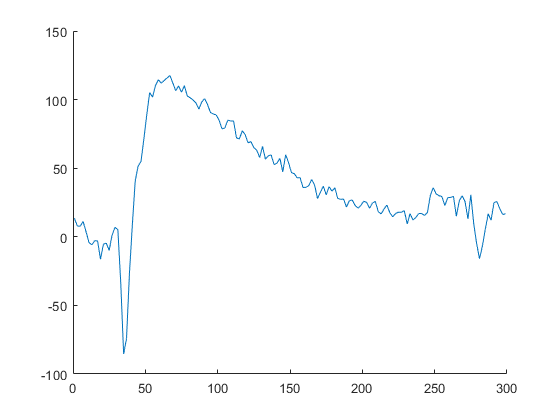

tempcrenEnds = 13.7507

found = 1

decays =    83.4186   45.8058   36.9209   62.1646   91.7060  184.0792  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


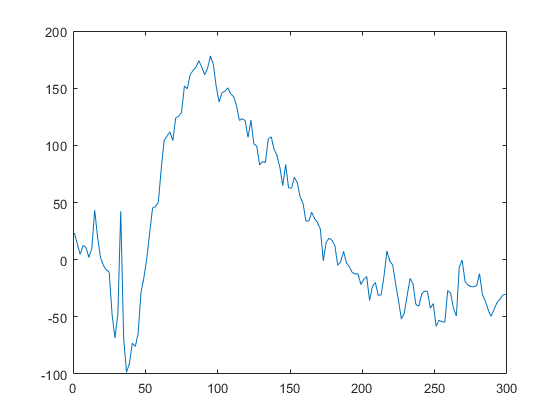

tempcrenEnds = -28.8297

found = 1

decays =    83.4186   45.8093   36.9209   62.1646   91.7060  184.0792  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


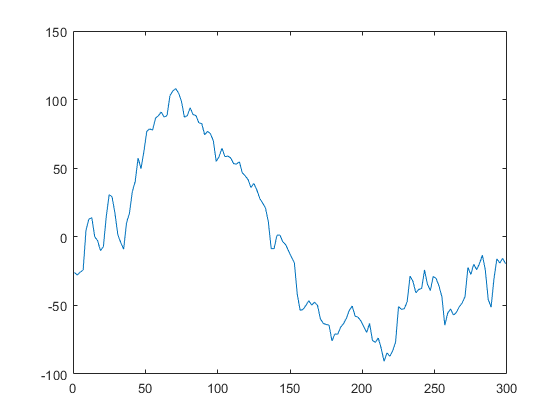

tempcrenEnds = -27.5126

found = 1

decays =    83.4186   45.8093   36.9195   62.1646   91.7060  184.0792  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


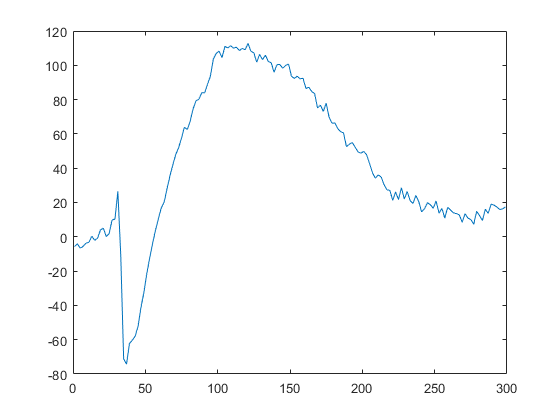

tempcrenEnds = 13.8384

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7060  184.0792  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


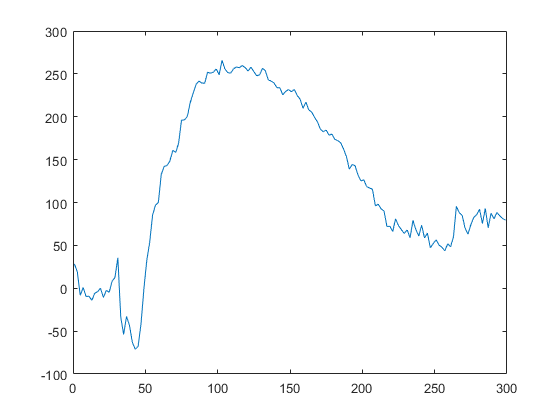

tempcrenEnds = 80.8620

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0792  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


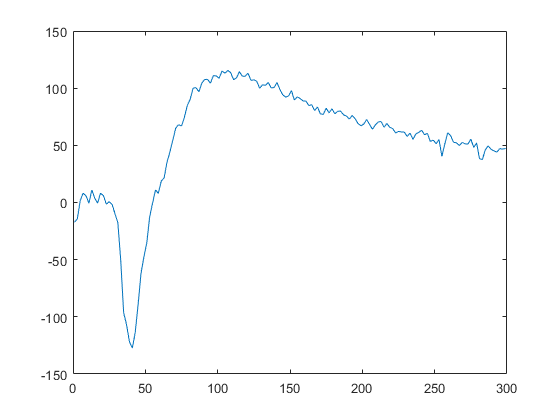

tempcrenEnds = 47.4355

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2029   73.2235  104.3299  173.8058  133.9728  336.6942


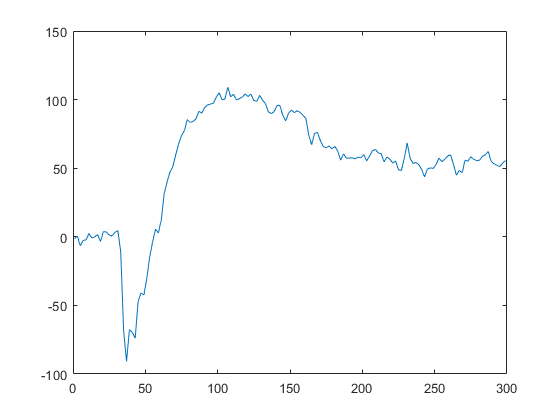

tempcrenEnds = 55.3321

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3299  173.8058  133.9728  336.6942


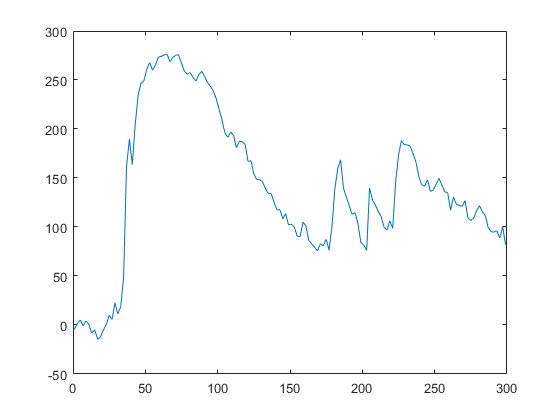

tempcrenEnds = 106.0013

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3299  173.8058  133.9728  336.6942


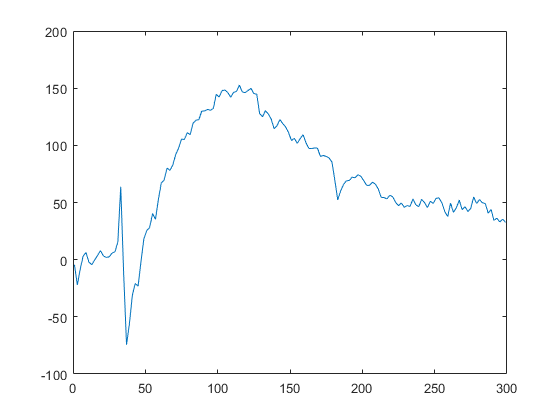

tempcrenEnds = 43.0345

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3296  173.8058  133.9728  336.6942


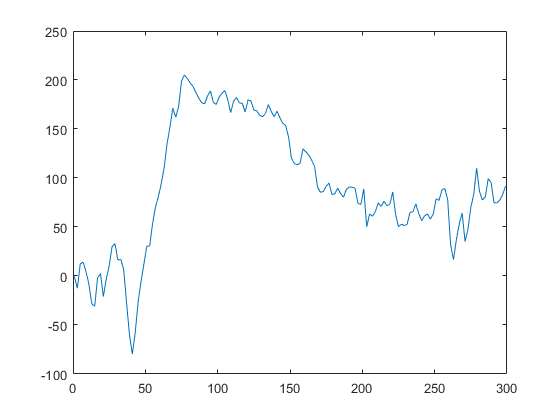

tempcrenEnds = 78.2504

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3296  173.8054  133.9728  336.6942


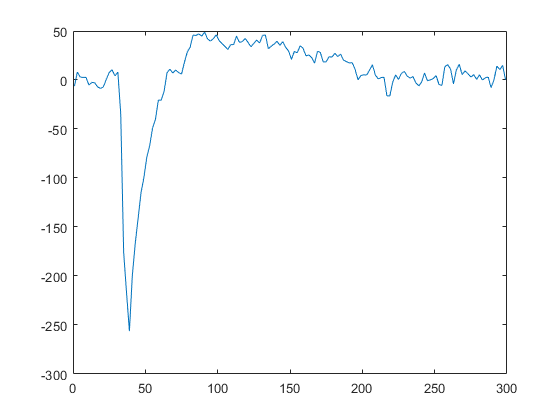

tempcrenEnds = 4.5909

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3296  173.8054  133.9708  336.6942


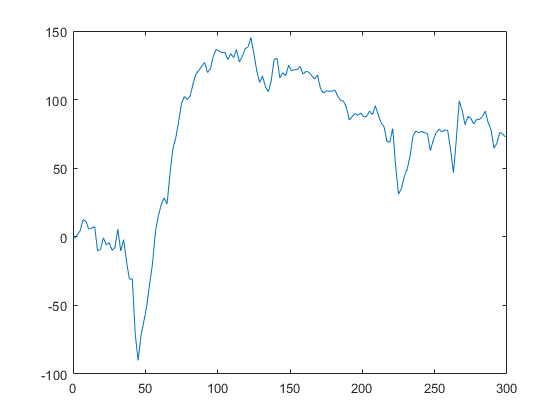

tempcrenEnds = 81.1562

found = 1

decays =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3296  173.8054  133.9708  336.6881


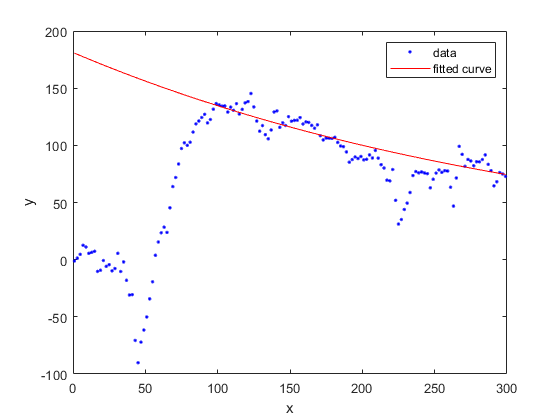

% %%analyze timecourses
figure; hold on;
time = 1:2:300;
for i = 1:size(WTcells,2)
    temptails = nanmean(WTcells(i).tailK - mean(WTcells(i).tailK(:,1:15),2),1); %subtract off baseline
    plot(time,temptails')
    [y,ind] = max(temptails(15:end));
    tempcrenEnds = mean(temptails(end-15:end))
    [edges] = [y y] - (y-tempcrenEnds)*[.8 .2];
    
    found = 0; %find 90% peak
    index = ind+1+15;
    while ~found
        if temptails(index) < edges(2)
            topindex = index;

            found = 1
        else
            index = index +1;
        end
    end
    
    found = 0; %find 10% peak
    index = ind+1+15;
    while ~found
        if temptails(index) < edges(1)
            botindex = index;
            found = 1;
        else
            index = index + 1;
        end
    end
    ft = fittype('a*exp(-x/b)','independent','x','dependent','y','coefficients',{'a','b'});
    exc = time < time(topindex) | time > time(botindex);
    startpoints = [100 40];
    f = fit(time',temptails','exp1','Exclude',exc);
    decays(i) = -1/f.b
    figure;
    plot(f,time,temptails);

   % waitforbuttonpress
end

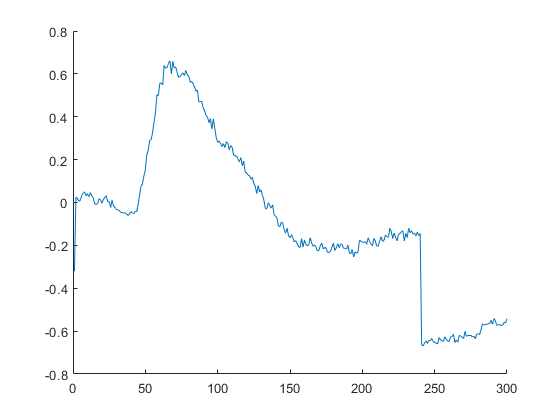

ind = 68

tempcrenEnds = -0.2543

found = 1

ans =      1   300


ind = 68

edges =    -0.1629    0.5689


topindex = 81

botindex = 150

decaysCren =    22.3238   47.2975   21.1970   45.3043   49.9409   42.6137   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


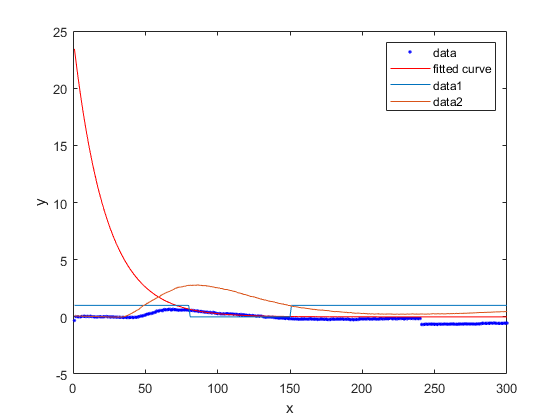

ind = 87

tempcrenEnds = 0.2902

found = 1

ans =      1   300


ind = 87

edges =     0.5401    2.5393


topindex = 101

botindex = 177

decaysCren =    22.3238   49.2296   21.1970   45.3043   49.9409   42.6137   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


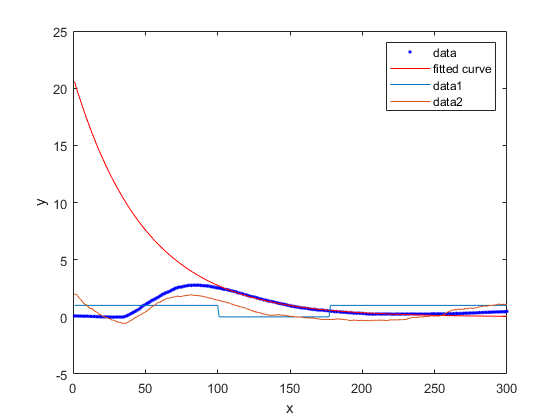

ind = 83

tempcrenEnds = -0.3216

found = 1

ans =      1   300


ind = 83

edges =    -0.0963    1.7066


topindex = 93

botindex = 164

decaysCren =    22.3238   49.2296   22.9666   45.3043   49.9409   42.6137   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


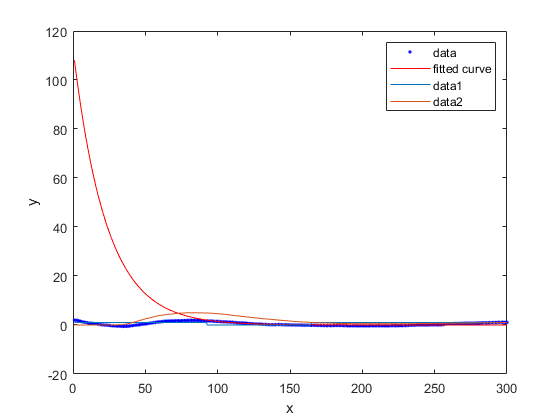

ind = 81

tempcrenEnds = 0.5394

found = 1

ans =      1   300


ind = 81

edges =     0.9899    4.5940


topindex = 101

botindex = 167

decaysCren =    22.3238   49.2296   22.9666   45.8168   49.9409   42.6137   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


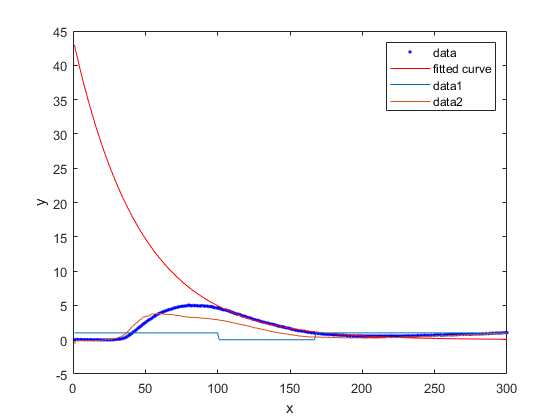

ind = 60

tempcrenEnds = 0.2492

found = 1

ans =      1   300


ind = 60

edges =     0.6079    3.4774


topindex = 75

botindex = 155

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6137   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


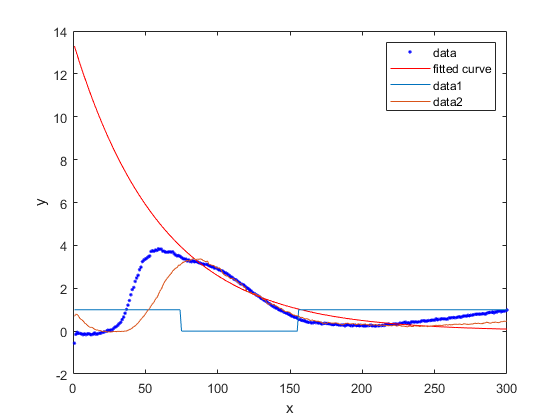

ind = 84

tempcrenEnds = 0.2908

found = 1

ans =      1   300


ind = 84

edges =     0.6003    3.0761


topindex = 96

botindex = 160

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   49.6684   21.3595   33.4347   24.4516   26.8399   26.7595


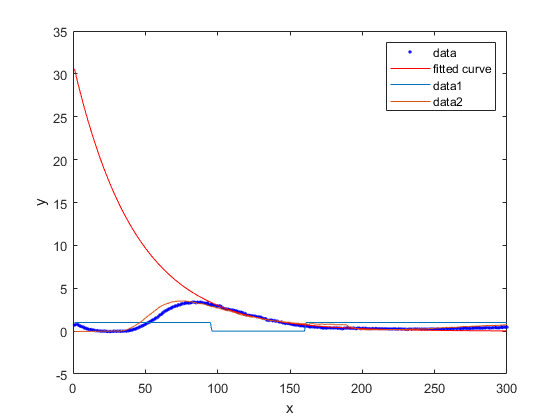

ind = 78

tempcrenEnds = 0.1674

found = 1

ans =      1   300


ind = 78

edges =     0.5029    3.1867


topindex = 90

botindex = 191

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319   21.3595   33.4347   24.4516   26.8399   26.7595


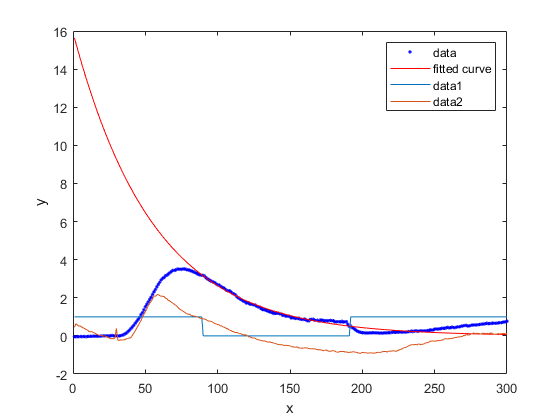

ind = 60

tempcrenEnds = -0.9106

found = 1

ans =      1   300


ind = 60

edges =    -0.6025    1.8617


topindex = 66

botindex = 156

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319  -12.0836   33.4347   24.4516   26.8399   26.7595


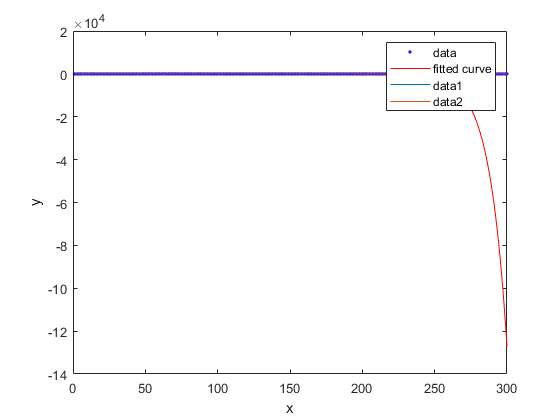

ind = 83

tempcrenEnds = 0.1694

found = 1

ans =      1   300


ind = 83

edges =     0.7307    5.2214


topindex = 95

botindex = 157

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319  -12.0836   34.2391   24.4516   26.8399   26.7595


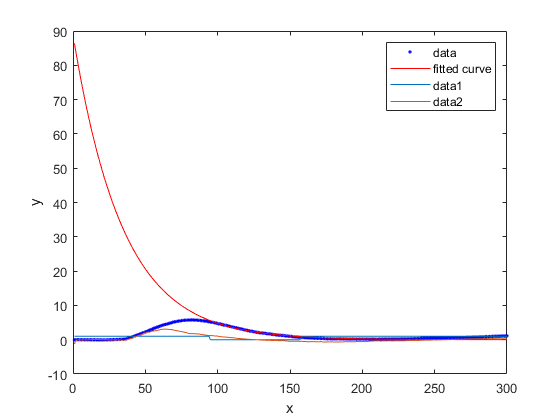

ind = 65

tempcrenEnds = -0.6795

found = 1

ans =      1   300


ind = 65

edges =    -0.3048    2.6928


topindex = 71

botindex = 147

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319  -12.0836   34.2391   22.2449   26.8399   26.7595


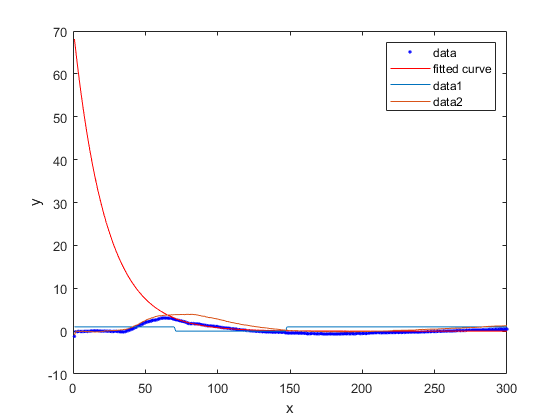

ind = 84

tempcrenEnds = -0.1824

found = 1

ans =      1   300


ind = 84

edges =     0.2280    3.5107


topindex = 90

botindex = 147

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319  -12.0836   34.2391   22.2449   28.2171   26.7595


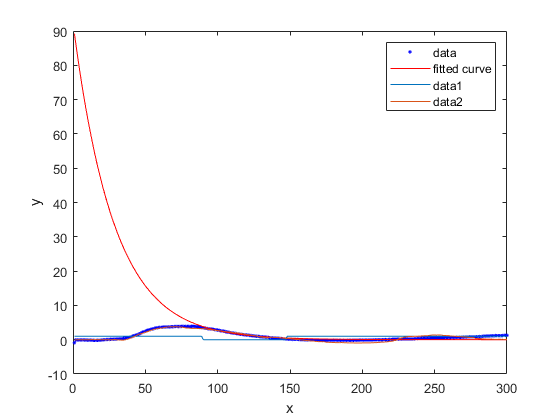

ind = 72

tempcrenEnds = -0.9619

found = 1

ans =      1   300


ind = 72

edges =    -0.4851    3.3291


topindex = 81

botindex = 168

decaysCren =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319  -12.0836   34.2391   22.2449   28.2171   33.8217


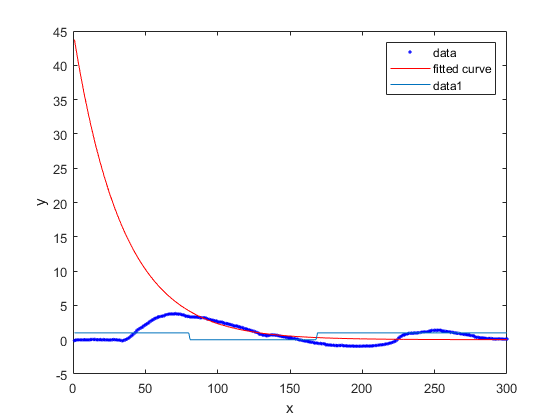


%%analyze timecourses
figure; hold on;
time = 1:1:300;
for i = 1:size(WTcellsCren,2)
    tempcren = nanmean(WTcellsCren(i).timecourse2 - mean(WTcellsCren(i).timecourse2(:,15:30),2),1); %subtract off baseline
    plot(time,tempcren')
    [y,ind] = max(tempcren(30:end));
    ind = ind + 30
    tempcrenEnds = min(tempcren(150:225))
    [edges] = [y y] - (y-tempcrenEnds)*[.9 .1];
    
    found = 0; %find 90% peak
    index = ind+1;
    while ~found
        if tempcren(index) < edges(2)
            topindex = index;
            found = 1
        else
            index = index +1;
        end
    end
    
    found = 0; %find 10% peak
    index = ind+1+15;
    while ~found
        if tempcren(index) < edges(1)
            botindex = index;
            found = 1;
        else
            index = index + 1;
        end
    end
    
    if botindex == topindex
        botindex = size(time,2);
    end
    size(tempcren)
    ind
    edges
    topindex
    botindex
    ft = fittype('a*exp(-x/b)','independent','x','dependent','y','coefficients',{'a','b'});
    exc = time < time(topindex) | time > time(botindex);
    startpoints = [100 40];
    f = fit(time',tempcren','exp1','Exclude',exc);
    decaysCren(i) = -1/f.b
    figure;
    plot(f,time,tempcren);
    hold on; plot(exc)
    %waitforbuttonpress
end

%%correlation analysis
h = figure;
j = figure;
for i = 1:size(WTcellsCren,2)
    tempcren = nanmean(WTcellsCren(i).timecourse);
    tempcren = tempcren - mean(tempcren);
    tempcren = tempcren(1:2:size(tempcren,2));
    temptails = nanmean(WTcells(i).tailK);
    temptails = temptails - mean(temptails);%subtract off baseline
    tempcurrents = resample(WTcells(i).dc,150,6000000);
    tempcurrents = tempcurrents - mean(tempcurrents);
    figure; plot(tempcurrents)
    if size(tempcren,2) == size(temptails,2)
        corr1(i) = corr(tempcren',temptails');
        corr2(i) = corr(tempcren', tempcurrents');
        figure(h);
        plot(tempcren',temptails','o'); hold on;
        figure(j);
        plot(tempcren',tempcurrents','o'); hold on;
    end
end    

dcrens = decaysCren([1:7 9:end])

dcrens =    22.3238   49.2296   22.9666   45.8168   60.4978   42.6524   55.5319   34.2391   22.2449   28.2171   33.8217


deca = decays(1:end-1)

deca =    83.4186   45.8093   36.9195   62.1649   91.7065  184.0794  136.2022   73.2235  104.3296  173.8054  133.9708


mean(dcrens)

ans = 37.9583

sterr(dcrens,2)

ans = 4.1227

mean(deca)

ans = 102.3300

sterr(deca,2)

ans = 14.8777

tails = []; steps = [];
for i=1:size(WTcells,2)
    tails = [tails; mean(WTcells(i).tailK,1)];
    steps = [steps; mean(WTcells(i).outK,1)];
end
tails = tails - mean(tails(:,1:15),2);
time = [0:size(tails,2)-1]*2;
figure; plot(time,tails','Color',[0.8 0.8 0.8]); hold on;
plot(time,nanmean(tails,1),'.','Color','k','LineWidth',2)
ylim([-600 300]);
yticks([-600:300:300]);
figQuality(gcf,gca,[1.75 1.25]);
export_fig('.\EPS Panels\groupTails.eps');
steps = steps - mean(steps(:,1:15),2);
figure; plot(steps','Color',[0.8 0.8 0.8]); hold on;
plot(nanmean(steps,1),'.','Color','k','LineWidth',2)


tails = []; steps = [];
for i=1:size(TMEMcells,2)
    tails = [tails; mean(TMEMcells(i).tailK,1)];
    steps = [steps; mean(TMEMcells(i).outK,1)];
end
tails = tails - mean(tails(:,1:15),2);
time = [0:size(tails,2)-1]*2;
figure; plot(time,tails','Color',[0.8 0.8 0.8]); hold on;
plot(time,nanmean(tails,1),'.','Color','k','LineWidth',2)
ylim([-600 300]);
yticks([-600:300:300]);
figQuality(gcf,gca,[1.75 1.25]);
export_fig('.\EPS Panels\TMEMgroupTails.eps');
steps = steps - mean(steps(:,1:15),2);
figure; plot(steps','Color',[0.8 0.8 0.8]); hold on;
plot(nanmean(steps,1),'.','Color','k','LineWidth',2)
ylim([-1000 400]  )


tails = []; steps = [];
for i=1:size(WTMRSKcells,2)
    tails = [tails; mean(WTMRSKcells(i).tailK,1)];
    steps = [steps; mean(WTMRSKcells(i).outK,1)];
end
tails = tails - mean(tails(:,1:15),2);
time = [0:size(tails,2)-1]*2;
figure; plot(time,tails','Color',[0.8 0.8 0.8]); hold on;
plot(time,nanmean(tails,1),'.','Color','k','LineWidth',2)
ylim([-600 300]);
yticks([-600:300:300]);
figQuality(gcf,gca,[1.75 1.25]);
export_fig('.\EPS Panels\WTMRSKgroupTails.eps');
steps = steps - mean(steps(:,1:15),2);
figure; plot(steps','Color',[0.8 0.8 0.8]); hold on;
plot(nanmean(steps,1),'.','Color','k','LineWidth',2)
ylim([-1000 400]  )

%%find example file for figure
filelist = loadFileList('.\Data\WT\*\*k1.abf')
colorTime = nan(150,3);
colorTime(1,:) = [0 0 0];
colorTime(20,:) = [40 140 255];
colorTime(40,:) = [0 150 50];
colorTime(150,:) = [204 204 20];
colorTime = fillmissing(colorTime,'linear')/255;

    [d,time,Hz] =loadPclampData(filelist{4});
    figure; plot(time,smooth(lowpass(d(:,1),50,Hz)),'Color','k','LineWidth',1)
    xlim([0 .40])
figQuality(gcf,gca,[2.75 1.8]);
export_fig('.\EPS Panels\Ksteps_MRS2365.eps')

    figure;
    for j=125:-4:1
        plot(time,lowpass(d(:,j),50,Hz),'Color',colorTime(j,:),'LineWidth',0.1); hold on;
    xlim([0 0.4])
    end



xlim([.243 .27]); ylim([-150 150]);
figQuality(gcf,gca,[1.5 2]);
export_fig('.\EPS Panels\Ksteps_MRS2365_tails.eps')


%WT + MRS2365 puff
file = 2;
 filelist = loadFileList('.\Data\WT\*\*k3_stats.mat');
 h = load(filelist{file})
% figure; plot(h.tempCell.tailK(2,:)','.')
% figure; plot(h.tempCell.outK(2,:)','.')
% ylim([1000 2400])
figdim1 = [1.75 .75];
figdim2 = [1.75 .6];
filelist = loadFileList('.\Data\WT\*\*k2.abf');
[d,time,fs] = loadPclampData(filelist{file});
dc = d;
dc(time > 0.08 & time < 0.6,:) = NaN;
t = size(d(:),1);
tp = [0:t-1]/fs;
dc = fillmissing(dc,'linear');
ha1 = figure; plot(tp,smooth(dc(:),10),'Color','k');
ylim([-200 100])
yticks([-200 100])
figQuality(gcf,gca,figdim1);

ha2 = figure; plot(h.tempCell.tailK(3,:)','.','Color','k');
figQuality(gcf,gca,figdim1);
ylim([-500 -100])
yticks([-500 -100])
% figure; plot(h.tempCell.outK(1,:)','.','Color','k');
% figQuality(gcf,gca,figdim1);
% export_fig('.\EPS Panels\WT_MRS2365puff_outK.eps');
filelist = loadFileList('.\Data\WT\*\*crenation_tc.mat');
h2 = load(filelist{file});
ha3 = figure; plot(h2.tempCell.timecourse2(3,:),'Color','k');
ylim([0 6]);
yticks([0 6]);
yticklabels({"0","10"})
figQuality(gcf,gca,figdim2);


handleTheSubplot({ha3,ha1,ha2},[3,1])
figQuality(gcf,gca,[1.75 2.5]);
export_fig('.\EPS Panels\WT_MRS2365_puff.eps');

%MRS2500 + K puff panel
file = 5;
filelist = loadFileList('.\Data\WT_MRS2500_Kpuff\*\*k3_stats.mat');
h = load(filelist{file})
% figure; plot(h.tempCell.tailK(2,:)','.')
% figure; plot(h.tempCell.outK(2,:)','.')
% ylim([1000 2400])
filelist = loadFileList('.\Data\WT_MRS2500_Kpuff\*\*k2.abf');
[d,time,fs] = loadPclampData(filelist{file});
dc = d;
dc(time > 0.08 & time < 0.6,:) = NaN;
t = size(d(:),1);
tp = [0:t-1]/fs;
dc = fillmissing(dc,'linear');
ha1 = figure; plot(tp,smooth(dc(:),10),'Color','k');
ylim([-200 100])
yticks([-200 100])

figQuality(gcf,gca,figdim1);


ha2 = figure; plot(h.tempCell.tailK(1,:)','.','Color','k');
ylim([-1200 -600]);
yticks([-1200 -600]);
yticklabels({'-120' '-600'});

figQuality(gcf,gca,figdim1);

% figure; plot(h.tempCell.outK(1,:)','.','Color','k');
% figQuality(gcf,gca,figdim1);
% export_fig('.\EPS Panels\WT_MRS2365puff_outK.eps');
filelist = loadFileList('.\Data\WT_MRS2500_Kpuff\*\*crenation_tc.mat');
h2 = load(filelist{5});
ha3 = figure; plot(msbackadj([1:300]',h2.tempCell.timecourse2(1,:)','WindowSize',20,'StepSize',20),'Color','k');
xlim([0 300]);

ylim([-0.1 6]);
yticks([0 6]);
yticklabels({'0','10'})
figQuality(gcf,gca,figdim2);

handleTheSubplot({ha3,ha1,ha2},[3,1])
figQuality(gcf,gca,[1.75 2.5]);
export_fig('.\EPS Panels\WT_MRS2500_kpuff.eps');

%TMEM16a cKO MRS2365 puff
file = 2;
 filelist = loadFileList('.\Data\TMEM\*\*k3_stats.mat');
 h = load(filelist{file})
% figure; plot(h.tempCell.tailK(2,:)','.')
% figure; plot(h.tempCell.outK(2,:)','.')
% ylim([1000 2400])
filelist = loadFileList('.\Data\TMEM\*\*k1.abf');
[d,time,fs] = loadPclampData(filelist{file});
dc = d;
dc(time > 0.075 & time < 0.8,:) = NaN;
t = size(d(:),1);
tp = [0:t-1]/fs;
dc = fillmissing(dc,'linear');
ha1 = figure; plot(tp,smooth(dc(:),10),'Color','k');
ylim([-200 100]);
yticks([-200 100])
figQuality(gcf,gca,figdim1);

ha2 = figure; plot(h.tempCell.tailK(1,:)','.','Color','k');
ylim([-400  0])
yticks([-400 0])
figQuality(gcf,gca,figdim1);

% figure; plot(h.tempCell.outK(3,:)','.','Color','k');
% figQuality(gcf,gca,figdim1);
% export_fig('.\EPS Panels\TMEM_MRS2365puff_outK.eps');
filelist = loadFileList('.\Data\TMEM\*\*crenation_tc.mat');
h2 = load(filelist{file});
ha3 = figure; plot(msbackadj([1:300]',h2.tempCell.timecourse2(1,:)','WindowSize',20,'StepSize',20),'Color','k');
ylim([-1 5]);
yticks([-1 5]);
yticklabels({"0","10"})
figQuality(gcf,gca,figdim2);

handleTheSubplot({ha3,ha1,ha2},[3,1])
figQuality(gcf,gca,[1.75 2.5]);
export_fig('.\EPS Panels\TMEM16AcKO_kpuff.eps');

%WT MRS Cells
WTMRScells = getKpuffStats('.\Data\WT_MRS2500_Kpuff\*',[1 1 1],1);
%TMEMcells = getStats('.\Data\TMEM\*',[1 1 1],1);


time = WTMRScells(1).time;
baseline = WTMRScells(1).baselineKresponse - mean(WTMRScells(1).baselineKresponse(1:2000));
MRS = WTMRScells(1).MRSKresponse - mean(WTMRScells(1).MRSKresponse(1:2000));
washout = WTMRScells(1).washoutKresponse - mean(WTMRScells(1).washoutKresponse(1:2000));
figure; plot(time,baseline,'Color','k'); hold on;
plot(time,MRS,'Color','r');
plot(time,washout,'Color',[0.7 0.7 0.7]);

figure;
plot(time,-baseline/min(baseline),'Color','k'); hold on;
plot(time,-MRS/min(MRS),'Color','r');
plot(time,-washout/min(washout),'Color',[0.7 0.7 0.7]);
xlim([0 10])

figure; plot(WTMRScells(1).d(:))